x=[1,1,1,1];w=[0:1:500]*2*pi/500;
[H]=freqz(x,1,w);
magH=abs(H);phaH=angle(H);
subplot(2,1,1);plot(w/pi,magH);grid;
xlabel('');ylabel('$\mid X\mid$',Interpreter='latex');
title('Amplitude of DTFT',Interpreter='latex');
subplot(2,1,2);plot(w/pi,phaH/pi*180);grid;
xlabel('Frequency : pi',Interpreter='latex');
ylabel('Degree',Interpreter='latex');
title('Phase of DTFT',Interpreter='latex');


  N=4;k=0:N-1;
  X=dft(x,N);
  magX=abs(X),phaX=angle(X)*180/pi;

magX =     4.0000    0.0000    0.0000    0.0000


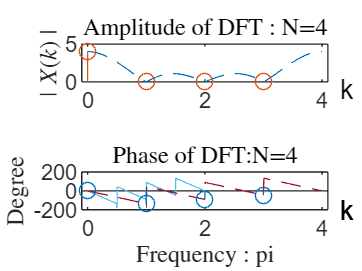

  subplot(2,1,1);plot(w*N/(2*pi),magH,'--');
  axis([-0.1,4.1,0,5]);hold on;
  stem(k,magX);
  ylabel('$\mid X(k)\mid$',Interpreter='latex');
  title('Amplitude of DFT : N=4',Interpreter='latex');
  text(4.3,-1,'k');
  hold off;
  subplot(2,1,2);plot(w*N/(2*pi),phaH*180/pi,'--');
  axis([-0.1,4.1,-200,200]);hold on;
  stem(k,phaX);
  ylabel('Degree',Interpreter='latex');
  title('Phase of DFT:N=4',Interpreter='latex');
  text(4.3,-200,'k');